t_a = 0:0.001:pi;

motor_mass = 0.750;
mount_mass = 0.087;

k_spring = 17112;

x_0 = 0.001*sin(t_a);

x_dot_0 = 0;

E_aluminium = 69*10^9;

mount_diameter = 0.008;
mount_length = 0.084;

I_mount = pi*(mount_diameter^4)/64;

k_eq_mount = 3*E_aluminium*I_mount/(mount_length^3) + k_spring;
m_eq = 33*(mount_mass+motor_mass)/140;

nat_freq_mount = sqrt(k_eq_mount/m_eq)

nat_freq_mount = 665.3216

freq_Hz = nat_freq_mount*0.159

freq_Hz = 105.7861

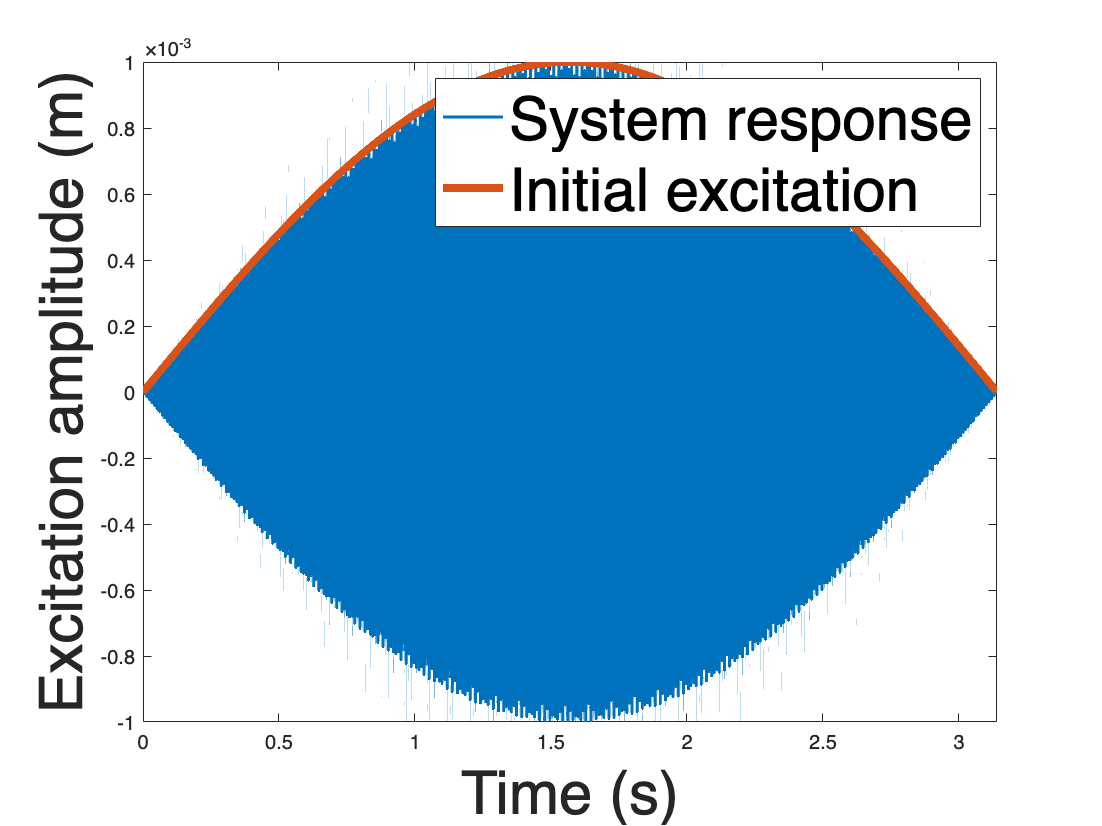


A = sqrt(x_0.^2 + (x_dot_0/nat_freq_mount).^2);
phase = atan(nat_freq_mount.*x_0./x_dot_0);

x = A.*sin(nat_freq_mount.*t_a + phase);

plot(t_a,x,LineWidth=1.5)
hold on
plot(t_a,x_0,LineWidth=4)
xlim([0 pi])
xlabel("Time (s)","FontSize",30)
ylabel("Excitation amplitude (m)","FontSize",30)
legend("System response","Initial excitation","FontSize",30)
hold off